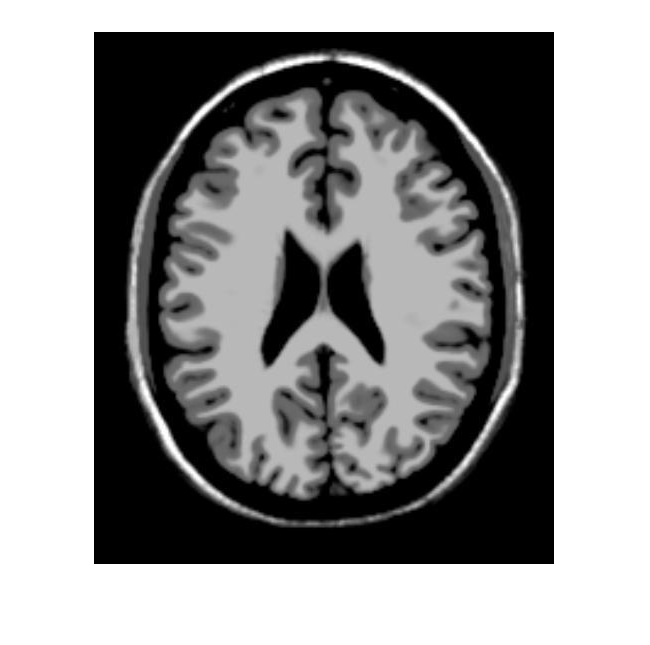

% Reading the first image
I1 = imread("HW1\T1.jpg");
J1 = im2double(I1);
imshow(J1);

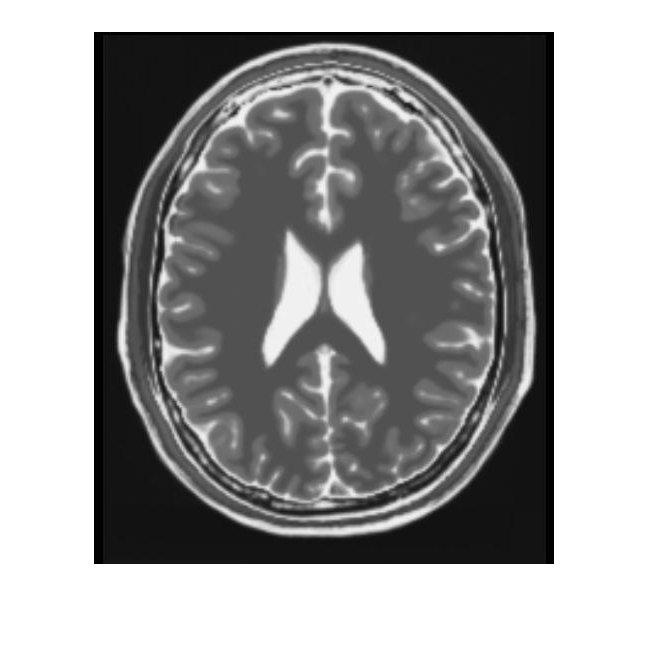

% Reading the second image
I2 = imread("HW1\T2.jpg");
J2 = im2double(I2);
imshow(J2);

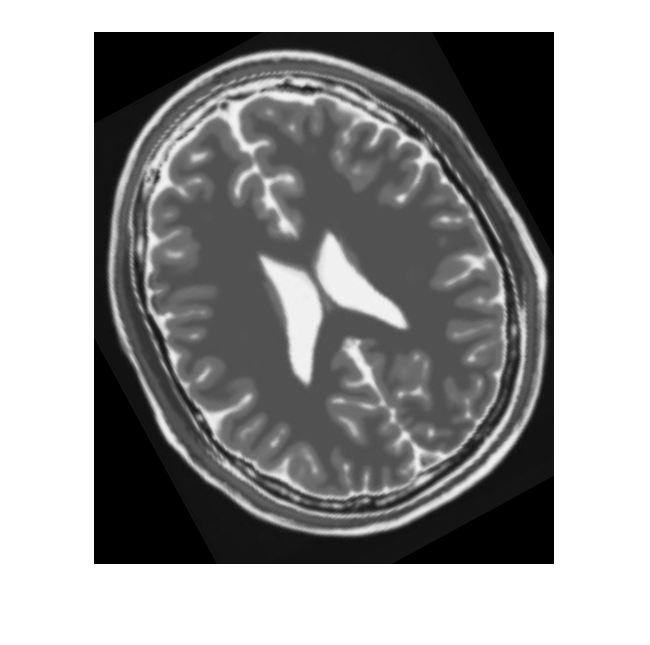

Jb = 1-J2;
%imshow(Jb);

% Rotating the second image using bilinear interpolation
J3 = imrotate(J2, 28.5, 'bilinear', 'crop');
imshow(J3);

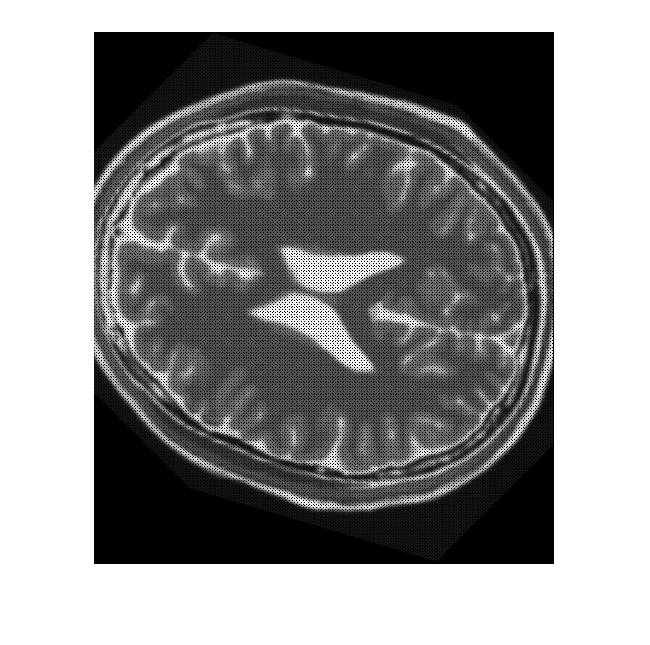


% J4 is the image that will be rotated manually
J4 = zeros(size(J3));
J4 = double(J4);

a=size(J4);
total_size = a(1)*a(2);

% Midpoint of the images which will be needed for rotation
middlex = a(2)/2.0;
middley = a(1)/2.0;

% The three metrics we require to calculate
NCC = zeros(91, 1);
JE = zeros(91, 1);
QMI = zeros(91, 1);

Y=zeros(91, 1);

% The joint histogram for the best estimated angle of rotation
best_joint_hist=[];
worst_joint_hist=[];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for angle = -45:45
    J4 = double(zeros(size(J3)));
    Y(angle+46, 1) = angle;
    % Performing rotation
    for i = 1:size(J3, 2)
        for j = 1:size(J3, 1)
            x = (i-middlex)*cosd(-angle)-(j-middley)*sind(-angle);
            y = (i-middlex)*sind(-angle)+(j-middley)*cosd(-angle);
            if((round(x)+middlex > 0 && round(y)+middley > 0)&&(round(y)+middley < 532 && round(x)+middlex < 460))
                J4(round(y)+middley, round(x)+middlex) = J3(j, i);
            end
        end
    end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Calculating NCC
    meanJ1 = mean(J1, "all");
    meanJ4 = mean(J4, "all");
    norm1 = 0.0;
    norm2 = 0.0;
    for a = 1:size(J3, 1)
        for b = 1:size(J3, 2)
            NCC(angle+46, 1) = NCC(angle+46, 1) + ((J1(a, b)-meanJ1)*(J4(a, b)-meanJ4));
            norm1 = norm1 + (J1(a, b)-meanJ1)^2;
            norm2 = norm2 + (J4(a, b)-meanJ4)^2;
        end
    end
    NCC(angle+46, 1) = NCC(angle+46, 1)/(sqrt(norm1*norm2));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Calculating JE and QMI
    joint_histogram = double(zeros(10));
    for yc = 1:size(J3, 1)
        for xc = 1:size(J3, 2)
            % The 10 bins are calculated using the ceiling of 10 times the
            % intensity. In case the intensity is 0, the first bin is
            % chosen, hence the max function
            joint_histogram(max(ceil(10*J1(yc, xc)), 1), max(ceil(10*J4(yc, xc)), 1)) = joint_histogram(max(ceil(10*J1(yc, xc)), 1), max(ceil(10*J4(yc, xc)), 1))+1;
        end
    end
    % Marginals as integrals of joint histogram
    margJ1 = double(sum(joint_histogram, 2))/total_size;
    margJ4 = double(sum(joint_histogram, 1))/total_size;
    
    % Both JE and NCC are summations over pairs of intensity bins
    for p = 1:10
        for q = 1:10
            temp = double(joint_histogram(p, q))/(total_size);
            temp2 = margJ1(p)*margJ4(q);
            if(temp ~= 0)
                JE(angle+46) = JE(angle+46) - (temp*log2(temp));
            end
            QMI(angle+46) = QMI(angle+46) +(temp-temp2)^2;
        end
    end
    if(angle == 28)
        best_joint_hist = joint_histogram;   
    end
    if(angle==-45)
        worst_joint_hist = joint_histogram;
    end
    imshow(J4);
end

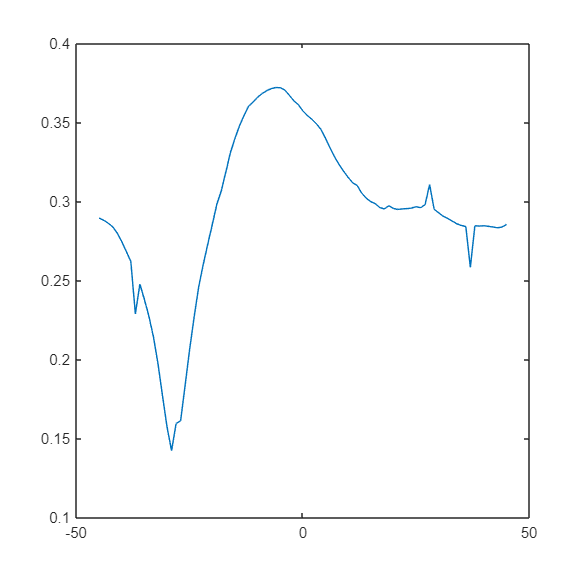


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Required plots
plot(Y, NCC);

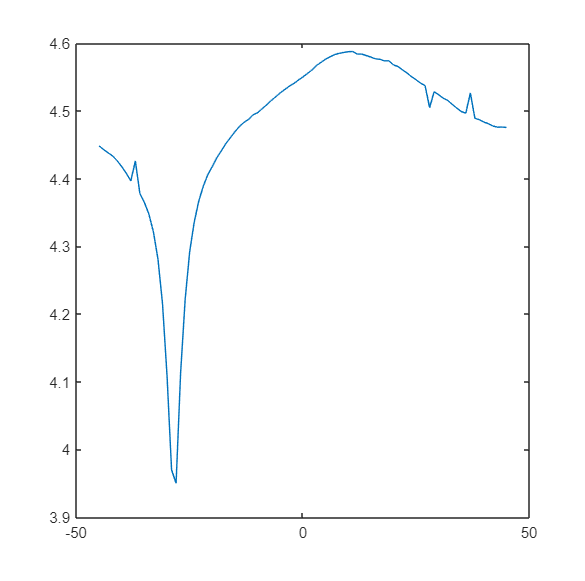

plot(Y, JE);

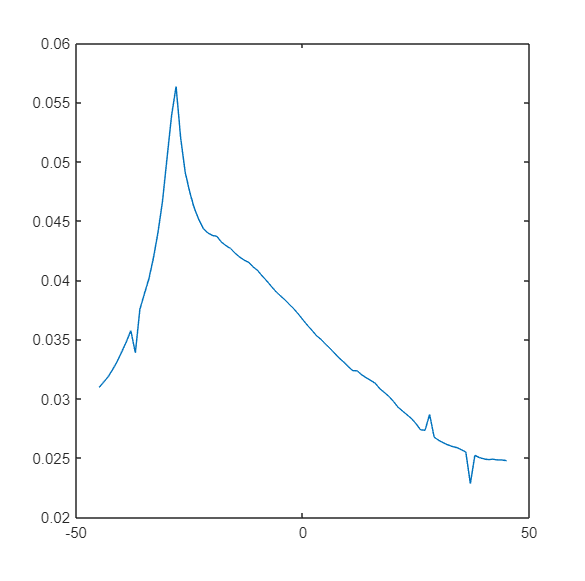

plot(Y, QMI);

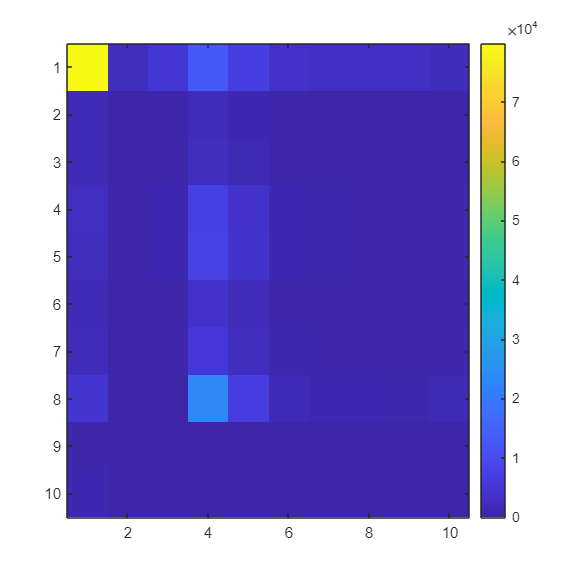

[final_value, final_angle] = min(NCC);
[final_value1, final_angle1] = min(JE);
[final_value2, final_angle2] = max(QMI);

imagesc(best_joint_hist);
colorbar;

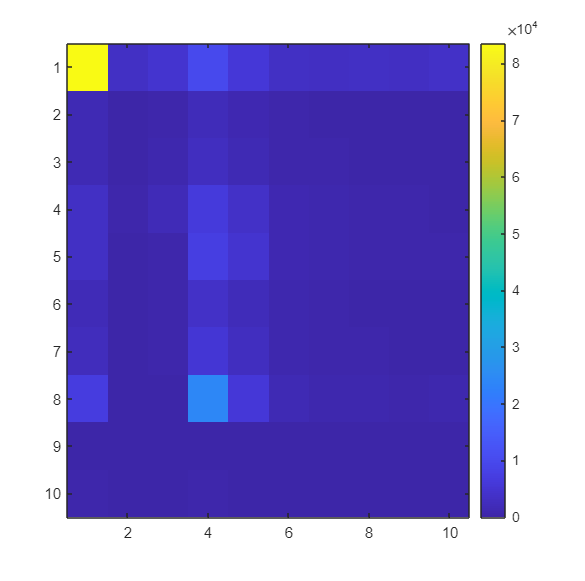


imagesc(worst_joint_hist);
colorbar;


final_angle(1)-46

ans = -29

final_angle1-46

ans = -28

final_angle2-46

ans = -28